# Initialize


clc;
clear;
close all;

startup;

Loading: E:\ChalmersOnedrive\OneDrive - Chalmers\文档\chalmers\sensor fusion\SensorFusion\project\Sensorfusion smartphone\sensordata.jar


********************
* SensorDataReader started on 192.168.31.220:3401
********************
Connection accepted from 192.168.31.228:38152


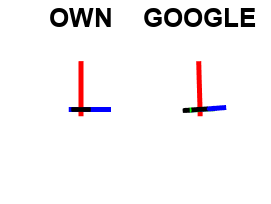

xhat = struct with fields:
    t: [0 0.0100 0.0200 0.0300 0.0397 0.0498 0.0598 0.0693 0.0793 0.0890 0.0990 0.1090 0.1185 0.1285 0.1385 0.1483 0.1583 0.1678 0.1778 0.1878 0.1975 0.2075 0.2175 0.2270 0.2370 0.2468 0.2568 0.2668 0.2750 0.2827 0.2885 0.2950 0.3027 0.3080 0.3147 … ]
    x: [4×1306 double]
    P: [4×4×1306 double]


meas = struct with fields:
         t: [0 0.0100 0.0200 0.0300 0.0397 0.0498 0.0598 0.0693 0.0793 0.0890 0.0990 0.1090 0.1185 0.1285 0.1385 0.1483 0.1583 0.1678 0.1778 0.1878 0.1975 0.2075 0.2175 0.2270 0.2370 0.2468 0.2568 0.2668 0.2750 0.2827 0.2885 0.2950 0.3027 0.3080 … ]
       acc: [3×1306 double]
       gyr: [3×1306 double]
       mag: [3×1306 double]
    orient: [4×1306 double]


% [xhat, meas] = Task5_filterTemplate()
[xhat, meas] = filterTemplate()



% load("placeflat.mat");


## plot

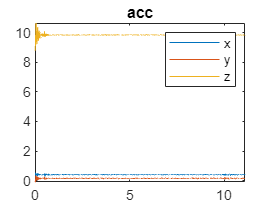


t= meas.t;

plotRead(meas.acc, t, 'acc',0);

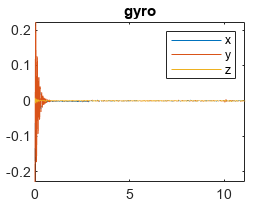

plotRead(meas.gyr, t, 'gyro',0);

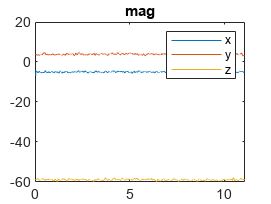

plotRead(meas.mag, t, 'mag',0)

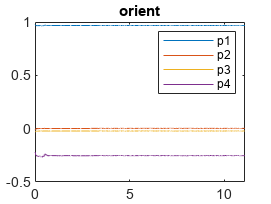

plotRead(meas.orient,t, 'orient',1)

## histogram & Gaussian

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
The mean of acc -X is 0.404113 
, the covariance of acc -X is 0.016355  

The mean of acc -Y is 0.155926 
, the covariance of acc -Y is 0.022011 

The mean of acc -Z is 9.851577 
, the covariance of acc -Z is 0.071911 



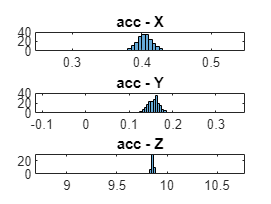

%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% % plot acc
plotHistograms(meas.acc, 'acc');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
The mean of gyro -X is -0.000300 
, the covariance of gyro -X is 0.012020  

The mean of gyro -Y is 0.000013 
, the covariance of gyro -Y is 0.016842 

The mean of gyro -Z is 0.000077 
, the covariance of gyro -Z is 0.000787 



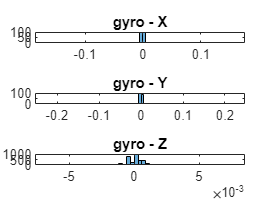

%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% 
% % plot gyro
plotHistograms(meas.gyr, 'gyro');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
The mean of mag -X is -4.973822 
, the covariance of mag -X is 0.303807  

The mean of mag -Y is 3.863684 
, the covariance of mag -Y is 0.311815 

The mean of mag -Z is -58.885704 
, the covariance of mag -Z is 0.340960 



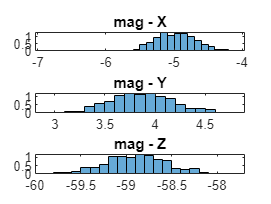

%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% 
% plot mag
plotHistograms(meas.mag, 'mag');

## Task 4

% % omega can just use reading from gyro
% omega = removeNaN(meas.gyr);
% % q can read from orientation
% x = removeNaN(meas.orient);

